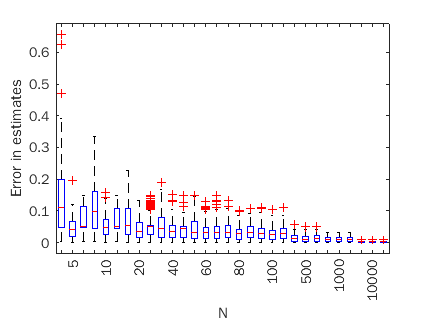

% Comparing Estimates

% Seed
rng(1);

% Declaring Variables
N = [5 10 20 40 60 80 100 500 1000 10000];
SS = length(N);
M = 150;
utrue = 10;
sigma = 4;
% storing error values
error = zeros(M,3 * SS);
uprior = 10.5;
sigmaprior = 1;

for k = 1:SS
  n = N(k);
  for m = 1:M
    % normal distribution with required parameters
    data = (sigma * randn(n,1)) + utrue;
    % ML estimate for mean
    mle = sum(data) / n; 
    % MAP1 estimate using gaussian prior
    map1 = ((mle) * sigmaprior^2 + uprior * (sigma^2 / n)) / (sigmaprior^2 + (sigma^2 / n));
    % MAP2 estimate using uniform prior
    map2 = mle; % in general
    % MAP cannot go beyond prior data region
    if map2 < 9.5
      map2 = 9.5;
    end
    if map2 > 11.5
      map2 = 11.5;
    end
    error(m,3 * k - 2) = abs(mle - utrue) / utrue;
    error(m,3 * k - 1) = abs(map1 - utrue) / utrue;
    error(m,3 * k) = abs(map2 - utrue) / utrue;
  end  
end

figure;
axis equal;
boxplot(error, 'Labels', {'','5','','','10','','','20','','','40','','','60','','','80','','','100','','','500','','','1000','','','10000',''});
xlabel('N');
ylabel('Error in estimates');